clear;
close all;
clc;

## Load the raw data

load('bp.mat');

## Plot the raw time signal

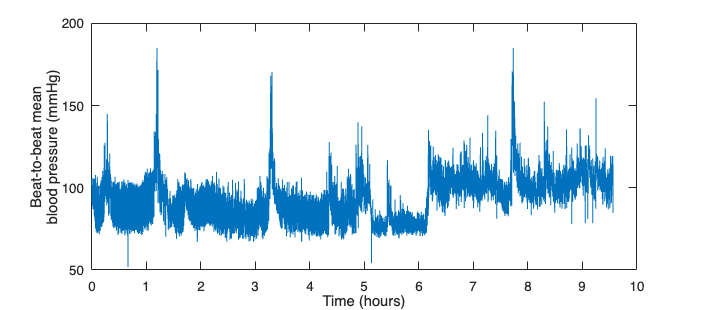

fs = 20;
t = (0:length(bp)-1)'/fs;
figure('Units','centimeters','Position',[0,0,25,11],'Color','w');
plot(t/3600, bp);
xlabel('Time (hours)');
ylabel({'Beat-to-beat mean','blood pressure (mmHg)'});

## Baseline attenuation: Highpass filter on the BP signal

The lower limit of the LF range is 0.04 Hz. With a cut-off frequency at 0.01 Hz, one can check (with the freqz function for instance) that we do not attenuate significantly any frequency component >= 0.04 Hz. Therefore, 0.01 Hz is a good trade-off between effective baseline cancellation and preservation of the frequency bands of interest.

[b,a] = butter(2, 0.01/(fs/2), 'high');
bp = filtfilt(b, a, bp);

## Spectrogram of the BP signal

Adjust the window duration below to a better value and explain your choice.

winduration = 4/0.04;    % Window duration in seconds: Find a better suited value
window = round(winduration*fs);
noverlap = round(0.95*winduration*fs);  % Overlap of 95%

figure('Units','centimeters','Position',[0,0,30,11],'Color','w');
spectrogram(bp, window, noverlap, [], fs, 'yaxis');
ylim([0,0.4]);
colormap('jet');
title('Spectrogram of the beat-to-beat mean BP signal');

% Adjust the lower limit of the colormap to a better value to improve the
% readability of the spectrogram.
cmaplowlim = -40%min(get(gca, 'clim')); % Lower colormap limit: Find a better value

cmaplowlim = -40

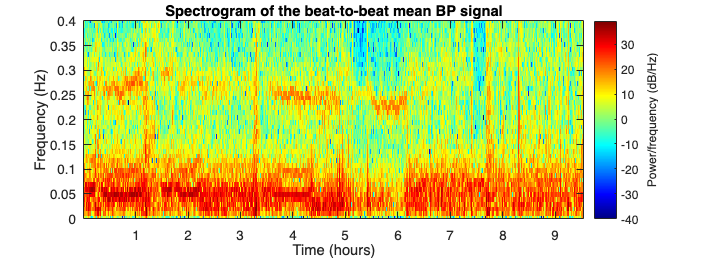

set(gca, 'clim', [cmaplowlim, max(get(gca, 'clim'))]);

### Question 1

We need a window length of at least 1/0.04 Hz = 25 s in order to capture the lowest frequencies. By taking a window of 25s, we will only capture one period. To increase the frequency resolution, we could take a multiple of 25 for the window duration, for instance 4*25= 100s. However, taking a larger than necessary window length would increase the frequency resolution but decrease the time resolution. It is therefore reasonable to assume that 100s is a good compromise and does not violate the stationarity assumption.

### Question 2

We notice visually that there are no values below -40 dB/Hz. Therefore, we set the minimum value of the axis to -40 dB/Hz.

### Question 3

When looking at these 3 timepoints, we notice that:

at T = 2 h, a strong component can be seen in the LF, indicating an important sympathetic component. A HF componement can also be seen, but with a limited impact.

at T = 4 h, there is still a strong LF, but an increase in HF can also be observed. 

and at T = 6 h, a clear change in balance can be observed, with now an important HF part dominating. The LF is less present at this period of time. 

Hence the sympathovagal balance moves toward a stronger sympathetic activity over the three timepoints.

### Question 4

It is possible to notice the differences in the sympathovagal balance. 

When **t = 2 hours**, we notice a dominant low frequency of the signal. Therefore, we can note the dominance of the sympathetical activity over the vagal activity ; 

When **t = 4 hours**, we see a mix of both high and low frequencies, hence there is a good balance between parasympathetical and vagal activities ; 

When **t = 6 hours**, we can hardly notice the low frequency in the signal, as the higher frequencies are much more dominant, from what we can deduce that there is a higher vagal activity at this time point. 

Of course, it is **much easier** to draw these conclusions when looking at the spectrograms, due to the fact that this one is plotted in 2 dimensions. 

**t = 2**

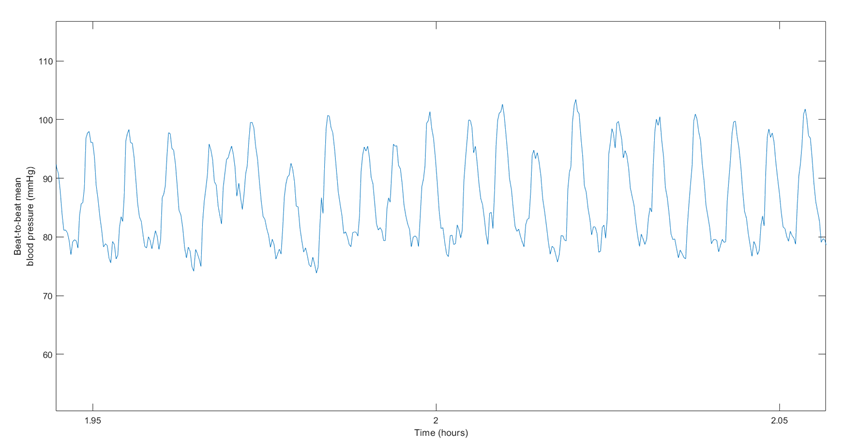

**t = 4**

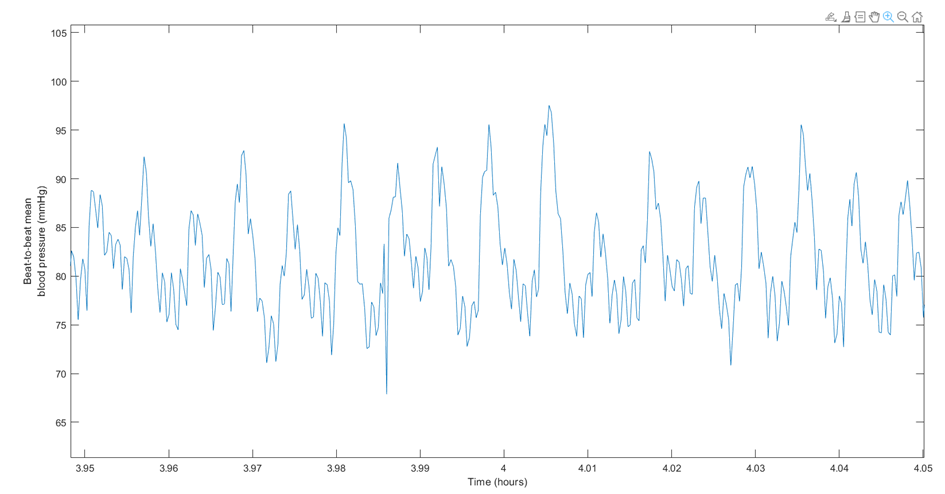

**t = 6**

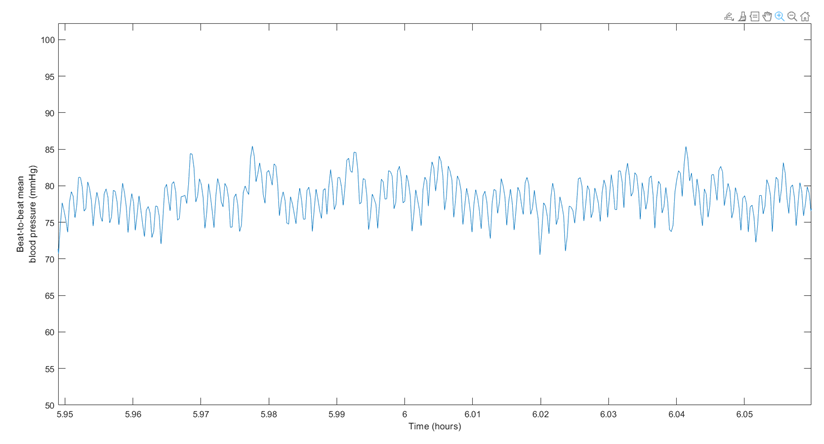

## Exercise: Respiration signal of a patient suffering from sleep apnea

### Question 1

We know that the signal has a frequency of 8/60 = 0.133 Hz, hence a period of 7.5s. Therefore, our window length must be at least 7.5 s to capture the frequency of one cycle of the normal respiratory activity, but it needs to be shorter than 20 seconds to capture the occasional periods of apnea, where the amplitude of the signal is equal to zero. 

**WL is in [7.5 , 20] s**